# **ELEC 4700 Assignment 2**

# **Finite Difference Method**

**Jay Maini 101037537**

**Feb 28, 2021**

# Part 1 - Using the Finite Difference Method

We can use the finite difference method to solve the matrix form of the problem GV=F for the electrostatic potential of a rectangular region. In this section we test multiple experiments to see the accuracy of this method.

Starting with a simple case where two of the boundary conditions are set at V0= 1 V and V=0. The top and bottom boundary conditions are not fixed.

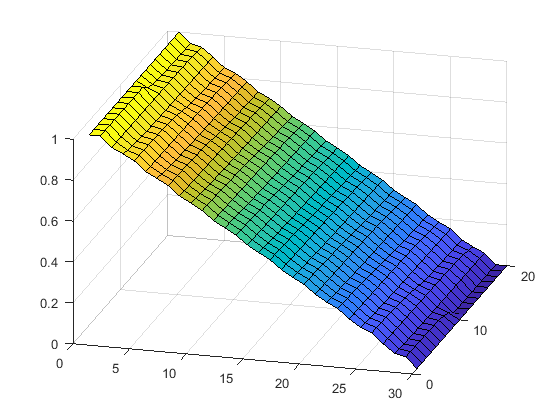

% Jay Maini 101037537
set(0, 'DefaultFigureWindowStyle','docked')
clear all
close all

v0 = 1;

%unequal array size
nx = 20;
ny = 30;
V = zeros(nx,ny);
G = sparse(nx*ny, nx*ny);
F = zeros(nx*ny,1);
Inclusion = 0;

for i = 1:nx
    for j = 1:ny
        m = j+(i-1)*ny;
        
        %Edge cases (BC's nodes)
        if (i == 1)
            F(m) = v0;
            G(m,m) = 1;
        elseif (i == nx)
            F(m) = 0;
            G(m,m) = 1;
%         elseif (j == ny)
%             F(m) = 0;
%             G(m,m) = 1;
%         elseif(j == 1)
%             F(m) = 0;
%             G(m,m) = 1;
        else
            %Inner region (set by FD equation)
            %set back to -4 for default
            G(m,m) = -4;
            
            %Define next/previous on the x and y axes
            npx = j+1 + (i-1)*ny;
            nmx = j-1 + (i-1)*ny;
            npy = j + (i-1+1)*ny;
            nmy = j + (i-1-1)*ny;
            
            G(m,npx) = 1; 
            G(m,nmx) = 1;
            G(m,npy) = 1;
            G(m,nmy) = 1;
        end
    end
end

%LU Decompsition
Varr = G\F;


    Varr_temp = reshape(Varr,nx,ny);
    figure(1)
    surf(Varr_temp)
    
view([15.600 28.800])

Next, we test the condition where all four of the boundary conditions are set. With the side conditions same as above, the new conditions for the top and bottom regions are V = 0 at y = 0 & y = W. The saddle plot is shown below.

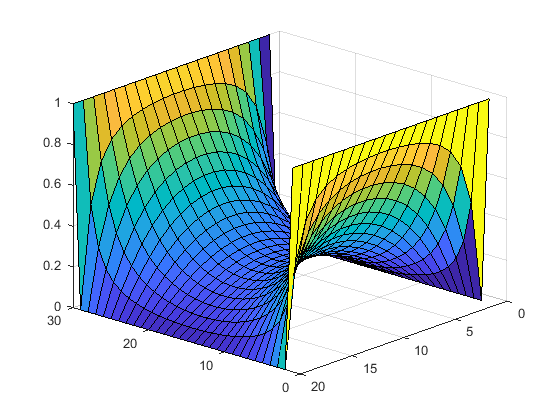

% Jay Maini 101037537
v0 = 1;

%unequal array size
nx = 30;
ny = 20;
V = zeros(nx,ny);
G = sparse(nx*ny, nx*ny);
F = zeros(nx*ny,1);
Inclusion = 0;

for i = 1:nx
    for j = 1:ny
        m = j+(i-1)*ny;
        
        %Edge cases (BC's nodes)
        if (i == 1)
            F(m) = v0;
            G(m,m) = 1;
        elseif (i == nx)
            F(m) = v0;
            G(m,m) = 1;
        elseif (j == ny)
            F(m) = 0;
            G(m,m) = 1;
        elseif(j == 1)
            F(m) = 0;
            G(m,m) = 1;
        else
            %Inner region (set by FD equation)
            %set back to -4 for default
            G(m,m) = -4;
            
            %Define next/previous on the x and y axes
            npx = j+1 + (i-1)*ny;
            nmx = j-1 + (i-1)*ny;
            npy = j + (i-1+1)*ny;
            nmy = j + (i-1-1)*ny;
            
            G(m,npx) = 1; 
            G(m,nmx) = 1;
            G(m,npy) = 1;
            G(m,nmy) = 1;
        end
    end
end

%LU Decompsition
Varr = G\F;

Varr_temp = reshape(Varr,ny,nx);
figure(2)
surf(Varr_temp)

view([-137.700 25.800])

We can check the accuracy of this model by comparing this plot to the analytical solution given by the following equation for the potential at each node:

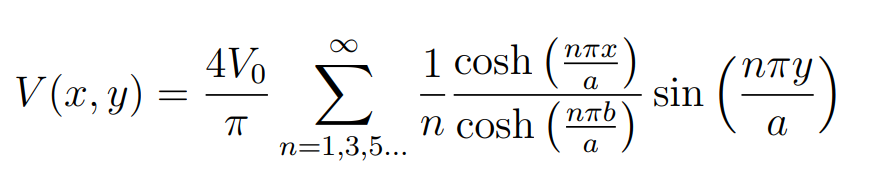

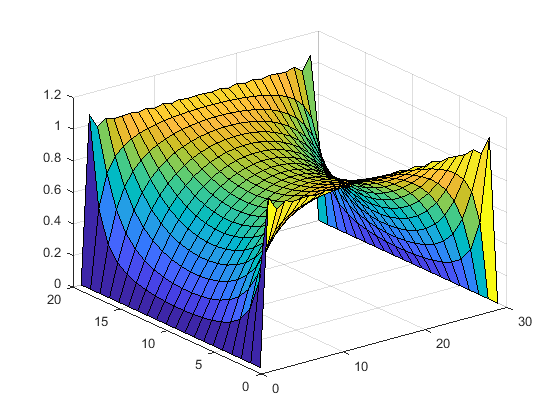

% Jay Maini 101037537
%Analytical solution
v0 = 1;

%unequal array size
nx = 20;
ny = 30;
V = zeros(nx,ny);

x = linspace(-nx/2,nx/2,nx);
y = linspace(0,ny,ny);
figure(3)

n = 1;
seriesSum = zeros(nx,ny);
a = ny;
b = nx/2;

while(n <= 90)
    for i = 1:nx
        for j = 1:ny
            seriesSum(i,j) = seriesSum(i,j) + ((cosh(n*pi*x(i)/a)/cosh(n*pi*b/a))*sin(n*pi*y(j)/a))/n;         
            V(i,j) = (4*v0/pi)*seriesSum(i,j);
        end
    end
    n = n + 2;
    surf(V)
    pause(0.05)
end

By animating the analytical solution, we can see the solution converge to 1 on the upper boundaries, but then diverge and continues to 'bounce' around the final solution. While the analytical computation is faster, its inability to fully converge at the solution remains a key disadvantage and highlights the usefulness to the numerical solution, alebit with a longer calculation time.

# Part 2 - Current Flow in a Bottlenecked Region using FDM

With the finite diference method validated in terms of its accuracy, we can now use it to solve a rectangular region of a set conductance and undergoing a electrostatic potential, but now with a bottleneck barrier of low-conductance boxes restricting the current flow. The following figures illustrate the conductance regions, and the resultant Electric fields, voltages, and current densities as a result.

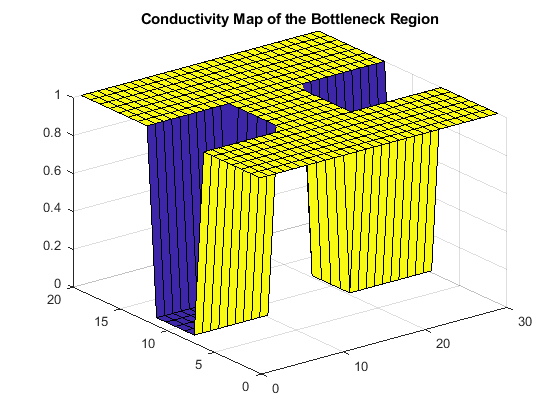

% Jay Maini 101037537
%EIPA
set(0, 'DefaultFigureWindowStyle','docked')
clear all
close all

v0 = 1;

%unequal array size
nx = 20;
ny = 30;
V = zeros(nx,ny);
G = sparse(nx*ny, nx*ny);
F = zeros(nx*ny,1);

%Easy adjustment for bottleneck size - useful for function
percent_open = 0.33;
percent_boundary = (1 - percent_open)/2;
b_height_1 = round(percent_boundary*ny);
b_height_2 = round(ny-percent_boundary*ny);

%Make conductivity array 
cMap = zeros(nx,ny) + 1;
%Create bottleneck areas
BNx = [(2/5)*nx (3/5)*nx];
%BNx = [b_height_1 b_height_2];
BNy1 = [1 b_height_1];
BNy2 = [b_height_2 ny];
%Modify cMap values

for o = BNx(1):BNx(2)
    for p = BNy1(1):BNy1(2)
        cMap(o,p) = 1e-2;
    end
    
    for u = BNy2(1):BNy2(2)
        cMap(o,u) = 1e-2;
    end
end
figure(1)
surf(cMap)
title('Conductivity Map of the Bottleneck Region')

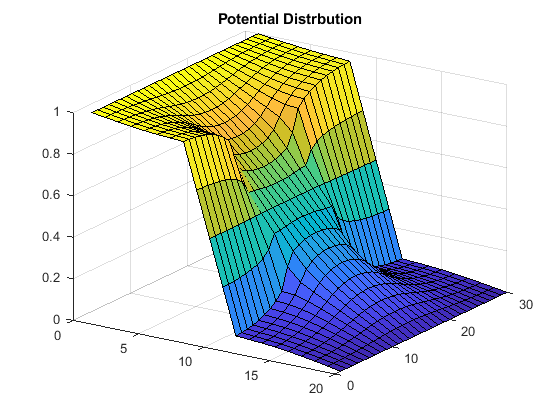



for i = 1:nx
    for j = 1:ny
        m = j+(i-1)*ny;
        
        %Edge cases (BC's nodes)
        if (i == 1)
            F(m) = v0;
            G(m,m) = 1;
        elseif (i == nx)
            F(m) = 0;
            G(m,m) = 1;
        elseif (j == 1)
            %Bottom side - only three resistors
            npy = j+1 + (i-1)*ny;
            npx = j + (i-1+1)*ny;
            nmx = j + (i-1-1)*ny;
            nmy = j-1 + (i-1)*ny;
            
            %Calculate resistances based on conductivity map
            rpx = (cMap(i,j) + cMap(i+1,j))/2;
            rmx = (cMap(i,j) + cMap(i-1,j))/2;
            rpy = (cMap(i,j) + cMap(i,j+1))/2;

            G(m,m) = -(rpx+rmx+rpy);
            G(m,npx) = rpx; 
            G(m,nmx) = rmx;
            G(m,npy) = rpy;
        elseif (j == ny)
            %top side - only three resistors
            nmy = j-1 + (i-1)*ny;
            npx = j + (i-1+1)*ny;
            nmx = j + (i-1-1)*ny;
            
            %Calculate resistances based on conductivity map
            rpx = (cMap(i,j) + cMap(i+1,j))/2;
            rmx = (cMap(i,j) + cMap(i-1,j))/2;
            rmy = (cMap(i,j) + cMap(i,j-1))/2;

            G(m,m) = -(rpx+rmx+rmy);
            G(m,npx) = rpx; 
            G(m,nmx) = rmx;
            G(m,nmy) = rmy;
        else
            %Inner region - four resistors
            %Define next/previous on the x and y axes
            npy = j+1 + (i-1)*ny;
            nmy = j-1 + (i-1)*ny;
            npx = j + (i-1+1)*ny;
            nmx = j + (i-1-1)*ny;
            
            %Calculate resistances based on conductivity map
            rpx = (cMap(i,j) + cMap(i+1,j))/2;
            rmx = (cMap(i,j) + cMap(i-1,j))/2;
            rpy = (cMap(i,j) + cMap(i,j+1))/2;
            rmy = (cMap(i,j) + cMap(i,j-1))/2;

            G(m,m) = -(rpx+rmx+rpy+rmy);
            G(m,npx) = rpx; 
            G(m,nmx) = rmx;
            G(m,npy) = rpy;
            G(m,nmy) = rmy;
        end
    end
end

%LU Decompsition
Varr = G\F;
Varr_temp = reshape(Varr,ny,nx);
figure(2)
surf(Varr_temp)
view([33.300 25.200])
title('Potential Distrbution')

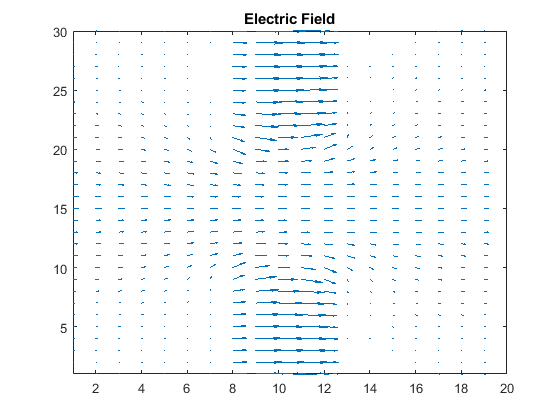




%Quiver plot
[Ex Ey] = gradient(-Varr_temp);
Jx = cMap' .*Ex;
Jy = cMap' .*Ey;
figure(3)
quiver(Ex,Ey)
title('Electric Field')
xlim([1 nx])
ylim([1 ny])

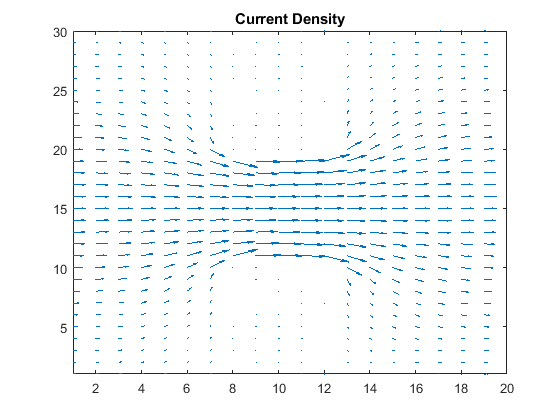

figure(4)
quiver(Jx,Jy)
title('Current Density')
xlim([1 nx])
ylim([1 ny])


%Output the current obtained
J = cMap' .*gradient(-Varr_temp);
%Peak current 
I_max = max(J, [], 'all')

I_max = 0.0852

I_avg = mean(J, 'all')

I_avg = 0.0235

As shown above, while the electric field through the box region is large, there is little current flow due to the substantially lower conductance. The maximum current density region is concentrated within the space between the barriers.

We can use this solution to investigate how current is affected by varying certain parameters of the of the simulation. The mesh density, bottleneck width, and box conductance can all be varied and plotted to see their individual affects on current.

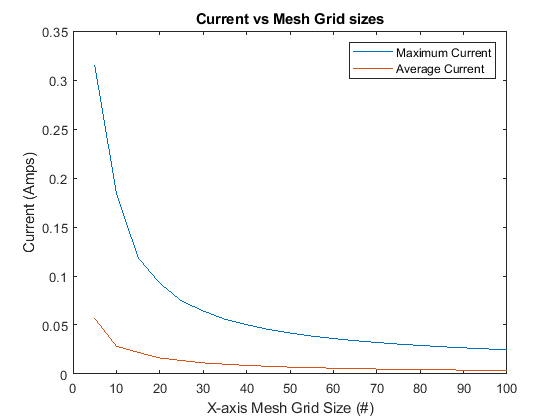

clear all

%default values for mesh grid, box reisstance, and neck size
mg = 20;
br = 1e-2;
bs = 0.2;

%Plot current vs mesh size
mg = linspace(5,100,100/5);
for i=1:length(mg)
    [I_max(i), I_avg(i)] = current_calculator(mg(i),br,bs);
end

figure(1)
plot(mg,I_max)
hold on
plot(mg,I_avg)
title('Current vs Mesh Grid sizes')
xlabel('X-axis Mesh Grid Size (#)')
ylabel('Current (Amps)')
legend('Maximum Current', 'Average Current')

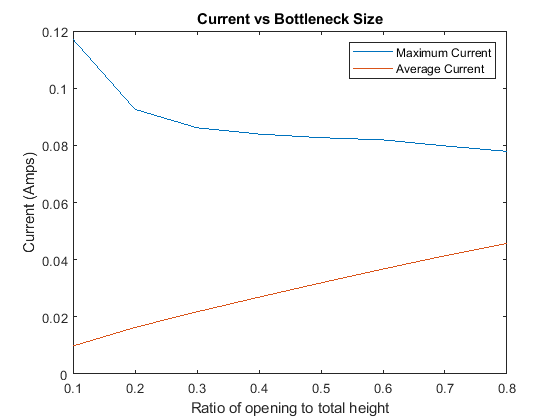

    
%plot current vs bottleneck size
I_max = 0;
I_avg = 0;
mg = 20;
bs = linspace(0.1,0.8,8);
for i=1:length(bs)
    [I_max(i), I_avg(i)] = current_calculator(mg,br,bs(i));
end

figure(2)
plot(bs,I_max)
hold on
plot(bs,I_avg)
title('Current vs Bottleneck Size')
xlabel('Ratio of opening to total height')
ylabel('Current (Amps)')
legend('Maximum Current', 'Average Current')

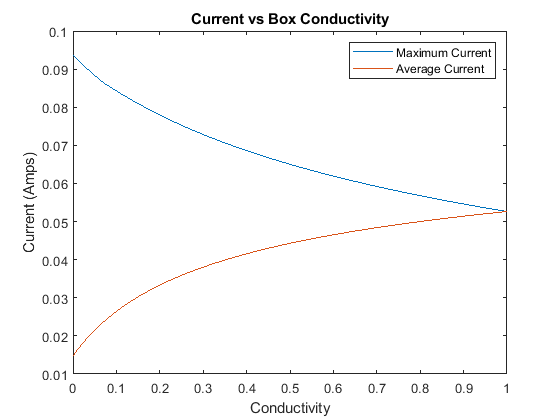


%plot current vs box resistance
I_max = 0;
I_avg = 0;
mg = 20;
bs = 0.2;
br = linspace(1e-6,1,100);
for i=1:length(br)
    [I_max(i), I_avg(i)] = current_calculator(mg,br(i),bs);
end

figure(3)
plot(br,I_max)
hold on
plot(br,I_avg)
title('Current vs Box Conductivity')
xlabel('Conductivity')
ylabel('Current (Amps)')
legend('Maximum Current', 'Average Current')

function [J_max, J_avg] = current_calculator(meshgridsize, boxresistance, bottleneck_size)
v0 = 1;

%unequal array size (Defaults 20 and 30)
nx = meshgridsize;
ny = round(1.5*meshgridsize);
V = zeros(nx,ny);
G = sparse(nx*ny, nx*ny);
F = zeros(nx*ny,1);

%Easy adjustment for bottleneck size - useful for function
percent_open = bottleneck_size; %0.2 default
percent_boundary = (1 - percent_open)/2;
b_height_1 = round(percent_boundary*ny);
b_height_2 = round(ny-percent_boundary*ny);

%Make conductivity array 
cMap = zeros(nx,ny) + 1;
%Create bottleneck areas
BNx = [(2/5)*nx (3/5)*nx];
%BNx = [b_height_1 b_height_2];
BNy1 = [1 b_height_1];
BNy2 = [b_height_2 ny];
%Modify cMap values

for o = BNx(1):BNx(2)
    for p = BNy1(1):BNy1(2)
        cMap(o,p) = boxresistance; %default 1e-2
    end
    
    for u = BNy2(1):BNy2(2)
        cMap(o,u) = boxresistance;
    end
end

for i = 1:nx
    for j = 1:ny
        m = j+(i-1)*ny;
        
        %Edge cases (BC's nodes)
        if (i == 1)
            F(m) = v0;
            G(m,m) = 1;
        elseif (i == nx)
            F(m) = 0;
            G(m,m) = 1;
        elseif (j == 1)
            %Bottom side - only three resistors
            npy = j+1 + (i-1)*ny;
            npx = j + (i-1+1)*ny;
            nmx = j + (i-1-1)*ny;
            nmy = j-1 + (i-1)*ny;
            
            %Calculate resistances based on conductivity map
            rpx = (cMap(i,j) + cMap(i+1,j))/2;
            rmx = (cMap(i,j) + cMap(i-1,j))/2;
            rpy = (cMap(i,j) + cMap(i,j+1))/2;

            G(m,m) = -(rpx+rmx+rpy);
            G(m,npx) = rpx; 
            G(m,nmx) = rmx;
            G(m,npy) = rpy;
        elseif (j == ny)
            %top side - only three resistors
            nmy = j-1 + (i-1)*ny;
            npx = j + (i-1+1)*ny;
            nmx = j + (i-1-1)*ny;
            
            %Calculate resistances based on conductivity map
            rpx = (cMap(i,j) + cMap(i+1,j))/2;
            rmx = (cMap(i,j) + cMap(i-1,j))/2;
            rmy = (cMap(i,j) + cMap(i,j-1))/2;

            G(m,m) = -(rpx+rmx+rmy);
            G(m,npx) = rpx; 
            G(m,nmx) = rmx;
            G(m,nmy) = rmy;
        else
            %Inner region - four resistors
            %Define next/previous on the x and y axes
            npy = j+1 + (i-1)*ny;
            nmy = j-1 + (i-1)*ny;
            npx = j + (i-1+1)*ny;
            nmx = j + (i-1-1)*ny;
            
            %Calculate resistances based on conductivity map
            rpx = (cMap(i,j) + cMap(i+1,j))/2;
            rmx = (cMap(i,j) + cMap(i-1,j))/2;
            rpy = (cMap(i,j) + cMap(i,j+1))/2;
            rmy = (cMap(i,j) + cMap(i,j-1))/2;

            G(m,m) = -(rpx+rmx+rpy+rmy);
            G(m,npx) = rpx; 
            G(m,nmx) = rmx;
            G(m,npy) = rpy;
            G(m,nmy) = rmy;
        end
    end
end

%LU Decompsition
Varr = G\F;
Varr_temp = reshape(Varr,ny,nx);

%Output the current obtained
J = cMap' .*gradient(-Varr_temp);
%Peak & average current 
J_max = max(J, [], 'all');
J_avg = mean(J, 'all');

end

These results give interesting findings. As the number of nodes increases, the average current falls off significantly due to higher spread of the values. Magnitudes are divided up amongst more nodes, and the maximum current also decreases.

Opening of the bottleneck allows a higher average current to flow through the wider region, but meanss the current is less compressed into that region, resulting in a lower maximum value. A similar result is shown as the conductivity of the bottleneck box region increases, alebit on a larger scale due to the logarithmic scaling of the conductance in this experiment.